# Q2. Creating Network - Image Classification *(50 points)*

## 0. Load data

***Data description**

`xTrain`: Training images

`yTrain`: `xTrain` Labels

`xTest`: Test images

`yTest`: `xTest` Labels

load("Q2_data.mat")

## 1. Data Understanding (20)

###     1.1. Understading GT (5)

      What classes does `yTain` and `yTest` have respectively?

yTrain_cate = categorical(yTrain)

yTrain_cate = 32000×1 categorical 배열
     6 
     9 
     9 
     4 
     1 
     1 
     8 
     3 
     7 
     2 
     9 
     9 
     9 
     3 
     2 
     6 
     4 
     3 
     6 
     2 
     5 
     4 
     0 
     9 
     1 
     3 
     4 
     0 
     3 
     7 


yTest_cate = categorical(yTest)

yTest_cate = 8000×1 categorical 배열
     2 
     7 
     4 
     7 
     6 
     6 
     3 
     0 
     3 
     5 
     2 
     9 
     8 
     7 
     4 
     3 
     1 
     5 
     9 
     1 
     9 
     6 
     7 
     1 
     4 
     1 
     8 
     7 
     6 
     5 


categories(yTrain_cate)

ans = 10×1 cell 배열
    {'0'}
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}
    {'6'}
    {'7'}
    {'8'}
    {'9'}


categories(yTest_cate)

ans = 10×1 cell 배열
    {'0'}
    {'1'}
    {'2'}
    {'3'}
    {'4'}
    {'5'}
    {'6'}
    {'7'}
    {'8'}
    {'9'}


###     1.2. Understading training images1 (3)

      Display the fifth image of `xTrain`.

size(xTrain)

ans =           32          32           3       32000


image1 = (xTrain(:,:,:,55))

image1 = image1(:,:,1) =

    0.5804    0.5176    0.5255    0.5765    0.6510    0.6667    0.6314    0.5098    0.5176    0.6431    0.6353    0.6471    0.6627    0.6471    0.6510    0.6353    0.6039    0.5765    0.4392    0.3647    0.3804    0.4000    0.4196    0.4235    0.4275    0.4275    0.4353    0.4902    0.5137    0.4863    0.4235    0.4863
    0.7725    0.6588    0.6902    0.7961    0.8078    0.8078    0.8000    0.5294    0.3608    0.7137    0.7216    0.6902    0.7922    0.7451    0.7020    0.5020    0.3098    0.2784    0.2549    0.2118    0.2275    0.2314    0.2392    0.2039    0.2353    0.3373    0.4588    0.6157    0.6824    0.6902    0.6353    0.5529
    0.7804    0.7804    0.8353    0.8941    0.9765    0.9255    0.8784    0.7490    0.3882    0.7961    0.9059    0.7451    0.6431    0.5725    0.5725    0.3294    0.1647    0.1725    0.1569    0.1529    0.1882    0.1529    0.1529    0.1333    0.1569    0.3804    0.6627    0.7686    0.7686    0.7137    0.6980    0.6000
    0.6588 

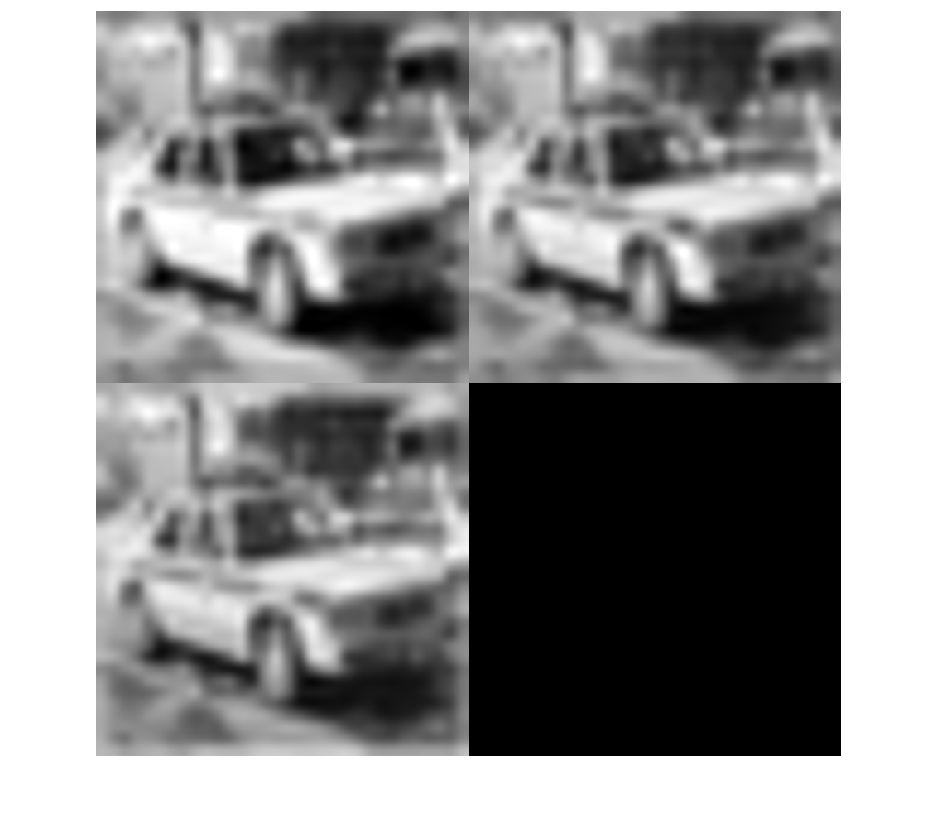

montage(rescale(image1))

###     1.3. Understading training images2 (7)

      How many images are class '5' within the first 500 images in `xTrain`.

class5 = find(yTrain_cate == '5')

class5 =     21
    32
    43
    58
    69
    71
   108
   124
   132
   133


numel(class5)

ans = 3179

###     1.4. Understading training images3 (5)      

      Display all images resulting from 1.3 as the figure below.

% for i = class5(1):class5(end)
%      imshow(xTrain(:,:,:,i))
% end

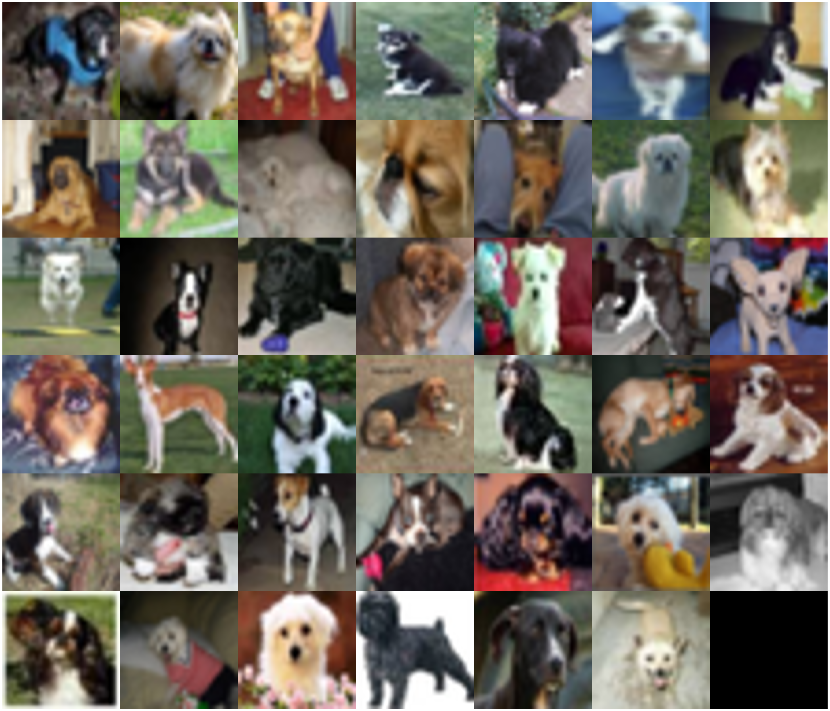

## 2. Creating Network (5 points with no error)

Create a Convolutional Neural Network.

layers = [imageInputLayer([32,32,3]);convolution2dLayer([2,2],100);reluLayer();maxPooling2dLayer([2,2]);...
    fullyConnectedLayer(10);softmaxLayer();classificationLayer()]

layers =   다음 계층을 포함한 7×1 Layer 배열:

     1   ''   영상 입력          32×32×3 영상 (정규화: 'zerocenter')
     2   ''   2차원 컨벌루션      100개 2×2 컨벌루션(스트라이드: [1  1], 채우기: [0  0  0  0])
     3   ''   ReLU             ReLU
     4   ''   2차원 최댓값 풀링   2×2 최댓값 풀링 (스트라이드: [1  1], 채우기: [0  0  0  0])
     5   ''   완전 연결          10 완전 연결 계층
     6   ''   소프트맥스         소프트맥스
     7   ''   분류 출력          crossentropyex

## 3. Training Network (5)

Create appropriate training options and train the network. The training options you **SHOULD KEEP** are as follows.

- Max epochs < 20

- Shuffle every epoch

- Schedule learning rate

It is highly recommended to adjust the parameters related to the learning rate.

opts = trainingOptions("adam","MaxEpochs",19,"Plots","training-progress",...
    "MiniBatchSize",320,"InitialLearnRate",0.01,"GradientThreshold",3,"LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",5,"LearnRateDropFactor",0.1,"Shuffle","every-epoch")

opts =   TrainingOptionsADAM - 속성 있음:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 0.0100
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 5
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: 3
                       MaxEpochs: 19
                   MiniBatchSize: 320
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'every-epoch'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'aut

newnet = trainNetwork(xTrain, yTrain_cate, layers, opts)

단일 CPU에서 훈련합니다.
입력 데이터의 정규화를 초기화하는 중입니다.


'yTrain_cate'은(는) 인식할 수 없는 함수 또는 변수입니다.

## 4. Evaluating Network (20)

Calculate the prediction accuracy on the test data.

- Accuracy >= 0.70             : 20 points

- 0.60 <= Accuracy < 0.70  : 15 points

- Accuracy <= 0.60             : 10 points

pred = classify(newnet, xTest)

다음 사용 중 오류가 발생함: DAGNetwork/classify
입력 크기가 잘못되었습니다. 입력 영상은 크기가 [224 224 3]이어야 합니다.

오류 발생: SeriesNetwork/classify (611번 라인)
            [labels, scores] = this.UnderlyingDAGNetwork.classify(X, varargin{:});

GT = yTest_cate
Acc = nnz(GT == pred)/numel(GT)